## GLM Modeling of the Clustered Multielectrode Data taken with Sparse Noise Stimulus

Add project source code to the path

clear all
project_root_dir = '.';
addpath(genpath(fullfile(project_root_dir, 'src')));

### ============= Load Data =============

Import and recreate the sparse noise stimulus

config_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\191010A\SN\processed\Acsn5x2.m';
configs = Config(config_file_path);
sn_stim = SparseNoiseStimulus(configs.config);

Import the timestamps for when the stimulus happened

crs_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\191010A\SN\processed\Acsn5x2.ch4.crs';
stim_ts = StimTimeStamps(crs_file_path, configs.config);

Import Corresponding Spike Event Timing Data

event_timing_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\191010A\SN\Acsn5x2_spikes.txt';
spike_times = SpikeTimes(event_timing_file_path);

Compute some basic statistics on the data

dtStim = (stim_ts.tempresolu); % time bin size for stimulus (s)
RefreshRate = 1/dtStim; % Refresh rate of the monitor
nT = size(sn_stim.stimulus, 3); % number of time bins in stimulus
nsp = length(spike_times.spike_t_vector); % number of spikes
  
% Print out some basic info
fprintf('--------------------------\n');

--------------------------


fprintf('Number of stim frames: %d  (%.1f minutes)\n', nT, nT*dtStim/60);

Number of stim frames: 8192  (3.9 minutes)


fprintf('Time bin size: %.1f ms\n', dtStim*1000);

Time bin size: 28.6 ms


fprintf('Number of spikes: %d (mean rate=%.1f Hz)\n\n', nsp, nsp/nT*RefreshRate);

Number of spikes: 1183 (mean rate=5.0 Hz)



### **============= Preprocessing Data for the Model ============**

Let's bin the spike train with the stimulus timestamps.

[tbin_centers, binned_spikes] = hist_bin_spikes(stim_ts, spike_times); %compute binned spike train

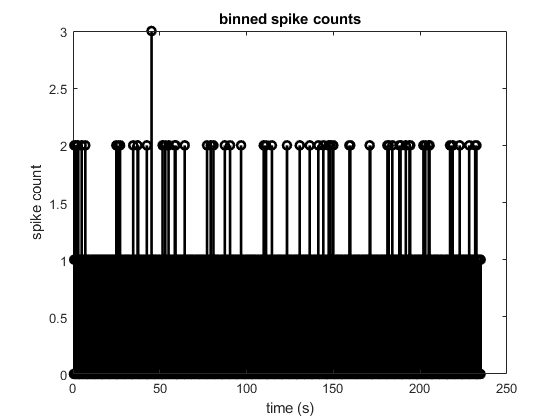

% Visualize the binned spike train
figure;
stem(tbin_centers,binned_spikes, 'k', 'linewidth', 2);
title('binned spike counts');
ylabel('spike count'); xlabel('time (s)');

Create Design Matrix

rf_temporal_len = 10; % frames
Xdsgn = make_design_matrix(sn_stim, rf_temporal_len);

dataset = DataSet(Xdsgn, binned_spikes);
train_data_pct = 0.7;
[train_var, train_lab, test_var, test_lab] = dataset.divide_train_test_data(train_data_pct);

### **=================  Plot STA  ================**

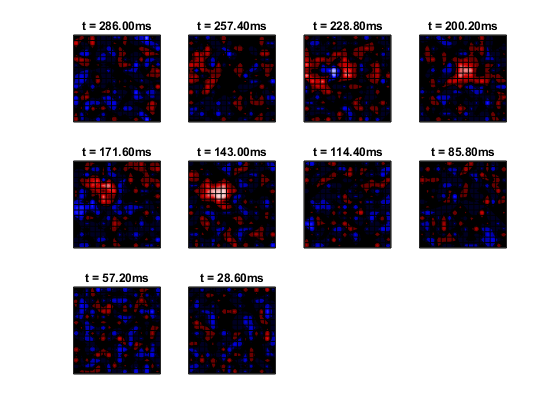

% It's extremely easy to compute the STA now that we have the design matrix
sta = (Xdsgn'*binned_spikes)/nsp;
sta = reshape(sta, [configs.config.gridsize, configs.config.gridsize, rf_temporal_len]);
plot_sta(sta, rf_temporal_len, stim_ts.tempresolu);

### **=================  Fit GLM  ================**

pGLMwts = glmfit(Xdsgn, binned_spikes, 'poisson','constant', 'on');

% plot whitened sta (weights from glm)
sta_glm = reshape(pGLMwts(2:end), [configs.config.gridsize,configs.config.gridsize,rf_temporal_len]);
plot_sta(sta_glm, rf_temporal_len, stim_ts.tempresolu);

### **======  Fit Temporal-Spatial Separable Filter  ======**

defaultprs = {'Gradobj','on', 'maxiter', 1000, 'maxfunevals', 1e9, 'Display', 'iter'};
opts = optimset(defaultprs{:});
Loss = @(rf_weights) neg_log_likli_poisson(Xdsgn, binned_spikes, rf_weights, stim_ts.tempresolu, rf_temporal_len, configs.config.gridsize);
init_weight = initialize_weight_from_sta(sta, 'separable');

[loss, dL] = neg_log_likli_poisson(Xdsgn, binned_spikes, init_weight, stim_ts.tempresolu, rf_temporal_len, configs.config.gridsize);

Neg Log Likelihood: 4481.273
gradient norm length: 119.922


[weight_final,neglogli,exitflag] = fminunc(Loss,init_weight,opts);

Neg Log Likelihood: 4481.273
gradient norm length: 119.922
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          4481.27                            27
Neg Log Likelihood: 4050.132
gradient norm length: 133.050
     1           2          4050.13      0.0369814             75  
Neg Log Likelihood: 39854531621.256
gradient norm length: 248252613416.370
Neg Log Likelihood: 54253.698
gradient norm length: 151264.136
Neg Log Likelihood: 4522.421
gradient norm length: 1550.670
Neg Log Likelihood: 3980.107
gradient norm length: 137.048
     2           6          3980.11       0.116814           44.6  
Neg Log Likelihood: 3914.705
gradient norm length: 151.076
     3           7          3914.71              1           89.8  
Neg Log Likelihood: 3869.845
gradient norm length: 86.906
     4           8          3869.84              1           53.9  
Neg Log Likelihood: 3832.260
grad

if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end

% plot temporal and spatial rf
temporal_rf = weight_final(1:rf_temporal_len);
spatial_rf = reshape(weight_final(rf_temporal_len+1:end), 16,16);

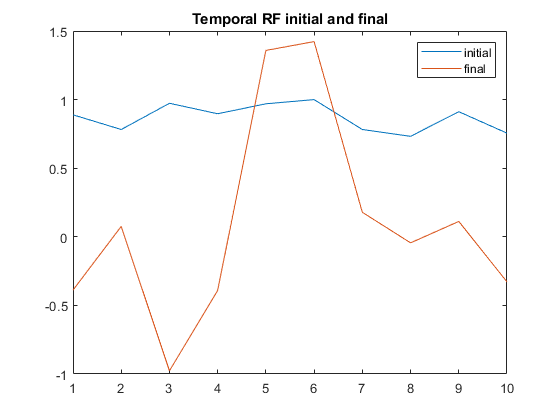

figure;
plot(init_weight(1:rf_temporal_len));
hold on;
plot(temporal_rf);
legend('initial', 'final')
title('Temporal RF initial and final')

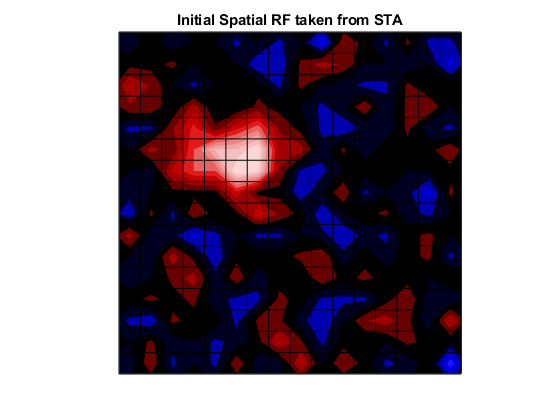

figure;

plot_sta(reshape(init_weight(rf_temporal_len+1:end),16,16), 1, 1);
title('Initial Spatial RF taken from STA')

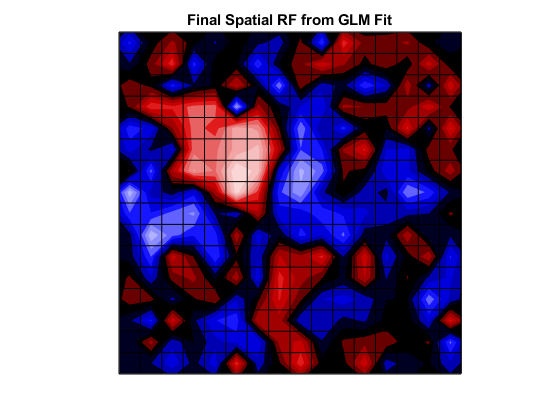

figure;
plot_sta(spatial_rf, 1, 1);
title('Final Spatial RF from GLM Fit')

### **======  Fit Temporal-Spatial + On / Off Separable Filter  ======**

defaultprs = {'Gradobj','on', 'maxiter', 1000, 'maxfunevals', 1e9, 'Display', 'iter'};
opts = optimset(defaultprs{:});
Loss = @(rf_weights) neg_log_likli_poisson(Xdsgn, binned_spikes, rf_weights, stim_ts.tempresolu, rf_temporal_len, configs.config.gridsize);;
init_weight = initialize_weight_from_sta(sta, 'separable');
spatial_rf_on = init_weight(rf_temporal_len+1:end);
spatial_rf_off = spatial_rf_on;
spatial_rf_on(spatial_rf_on<0)=0;
spatial_rf_off(spatial_rf_off>0)=0;
init_weight_onoff = [init_weight(1:rf_temporal_len); spatial_rf_on; spatial_rf_off];

[weight_final,neglogli,exitflag] = fminunc(Loss,init_weight_onoff,opts);

Neg Log Likelihood: 4474.484
gradient norm length: 386.974
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          4474.48                          44.6
Neg Log Likelihood: 6610.111
gradient norm length: 6909.193
Neg Log Likelihood: 3346.954
gradient norm length: 111.402
     1           3          3346.95      0.0112121           35.1  
Neg Log Likelihood: 3437.477
gradient norm length: 761.369
Neg Log Likelihood: 3310.389
gradient norm length: 206.913
     2           5          3310.39       0.417101             61  
Neg Log Likelihood: 3470.325
gradient norm length: 1303.511
Neg Log Likelihood: 3161.173
gradient norm length: 320.382
     3           7          3161.17            0.5           98.6  
Neg Log Likelihood: 3040.241
gradient norm length: 134.532
     4           8          3040.24              1           58.1  
Neg Log Likelihood: 3022.110
gradient norm length: 

if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end

% plot temporal and spatial rf
temporal_rf_onoff = weight_final(1:rf_temporal_len);
spatial_rf_on = reshape(weight_final(rf_temporal_len+1:rf_temporal_len+16^2), 16,16);
spatial_rf_off = reshape(weight_final(rf_temporal_len+16^2+1:end), 16,16);

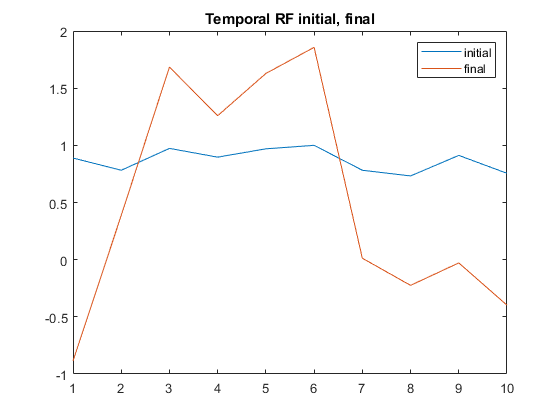

figure;
plot(init_weight_onoff(1:rf_temporal_len));
hold on;
plot(temporal_rf_onoff);
legend('initial', 'final')
title('Temporal RF initial, final')

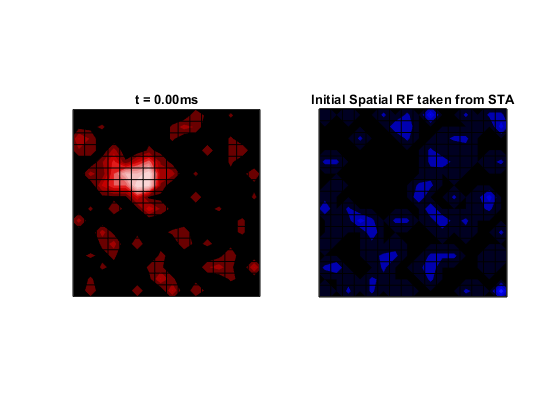

figure;
plot_sta(reshape(init_weight_onoff(rf_temporal_len+1:end),16,16,2), 2, 0);
title('Initial Spatial RF taken from STA')

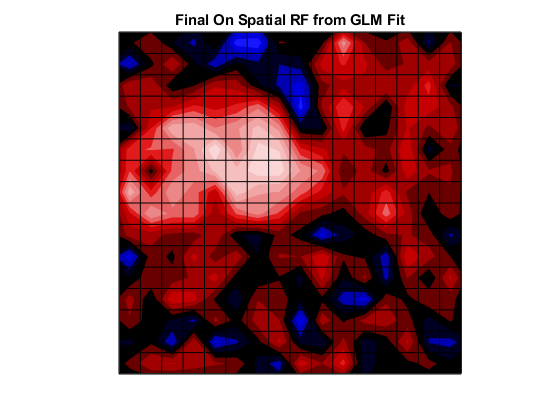

figure;
plot_sta(spatial_rf_on, 1, 0);
title('Final On Spatial RF from GLM Fit')

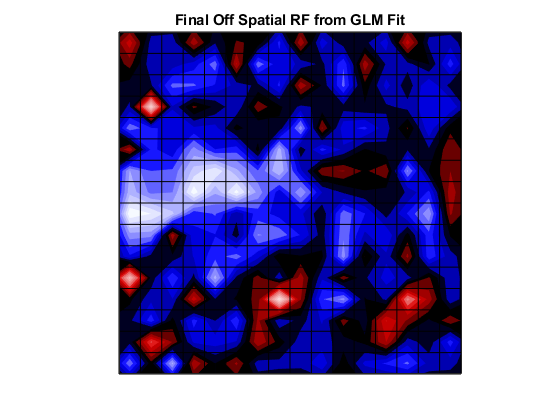

figure;
plot_sta(spatial_rf_off, 1, 0);
title('Final Off Spatial RF from GLM Fit')